### **Q1计算正态分布的概率密度函数**

q1_1(0) 

ans = 0.3989

q1_1(1) 

ans = 0.2420

% q1_1([-1 0 2]) 
q1_2([-1 0 2]) 

ans =     0.2420    0.3989    0.0540


q1_3(0,-1,2)

ans = 0.1760

q1_3([-1 0 2],1,1.5)

ans =     0.1093    0.2130    0.2130


q1_4([-1 0 2])  

ans =     0.2420    0.3989    0.0540


q1_4([-1 0 2],1)  

ans =     0.0540    0.2420    0.2420


q1_4([-1 0 2],1,1.5)  

ans =     0.1093    0.2130    0.2130


拓展：绘图

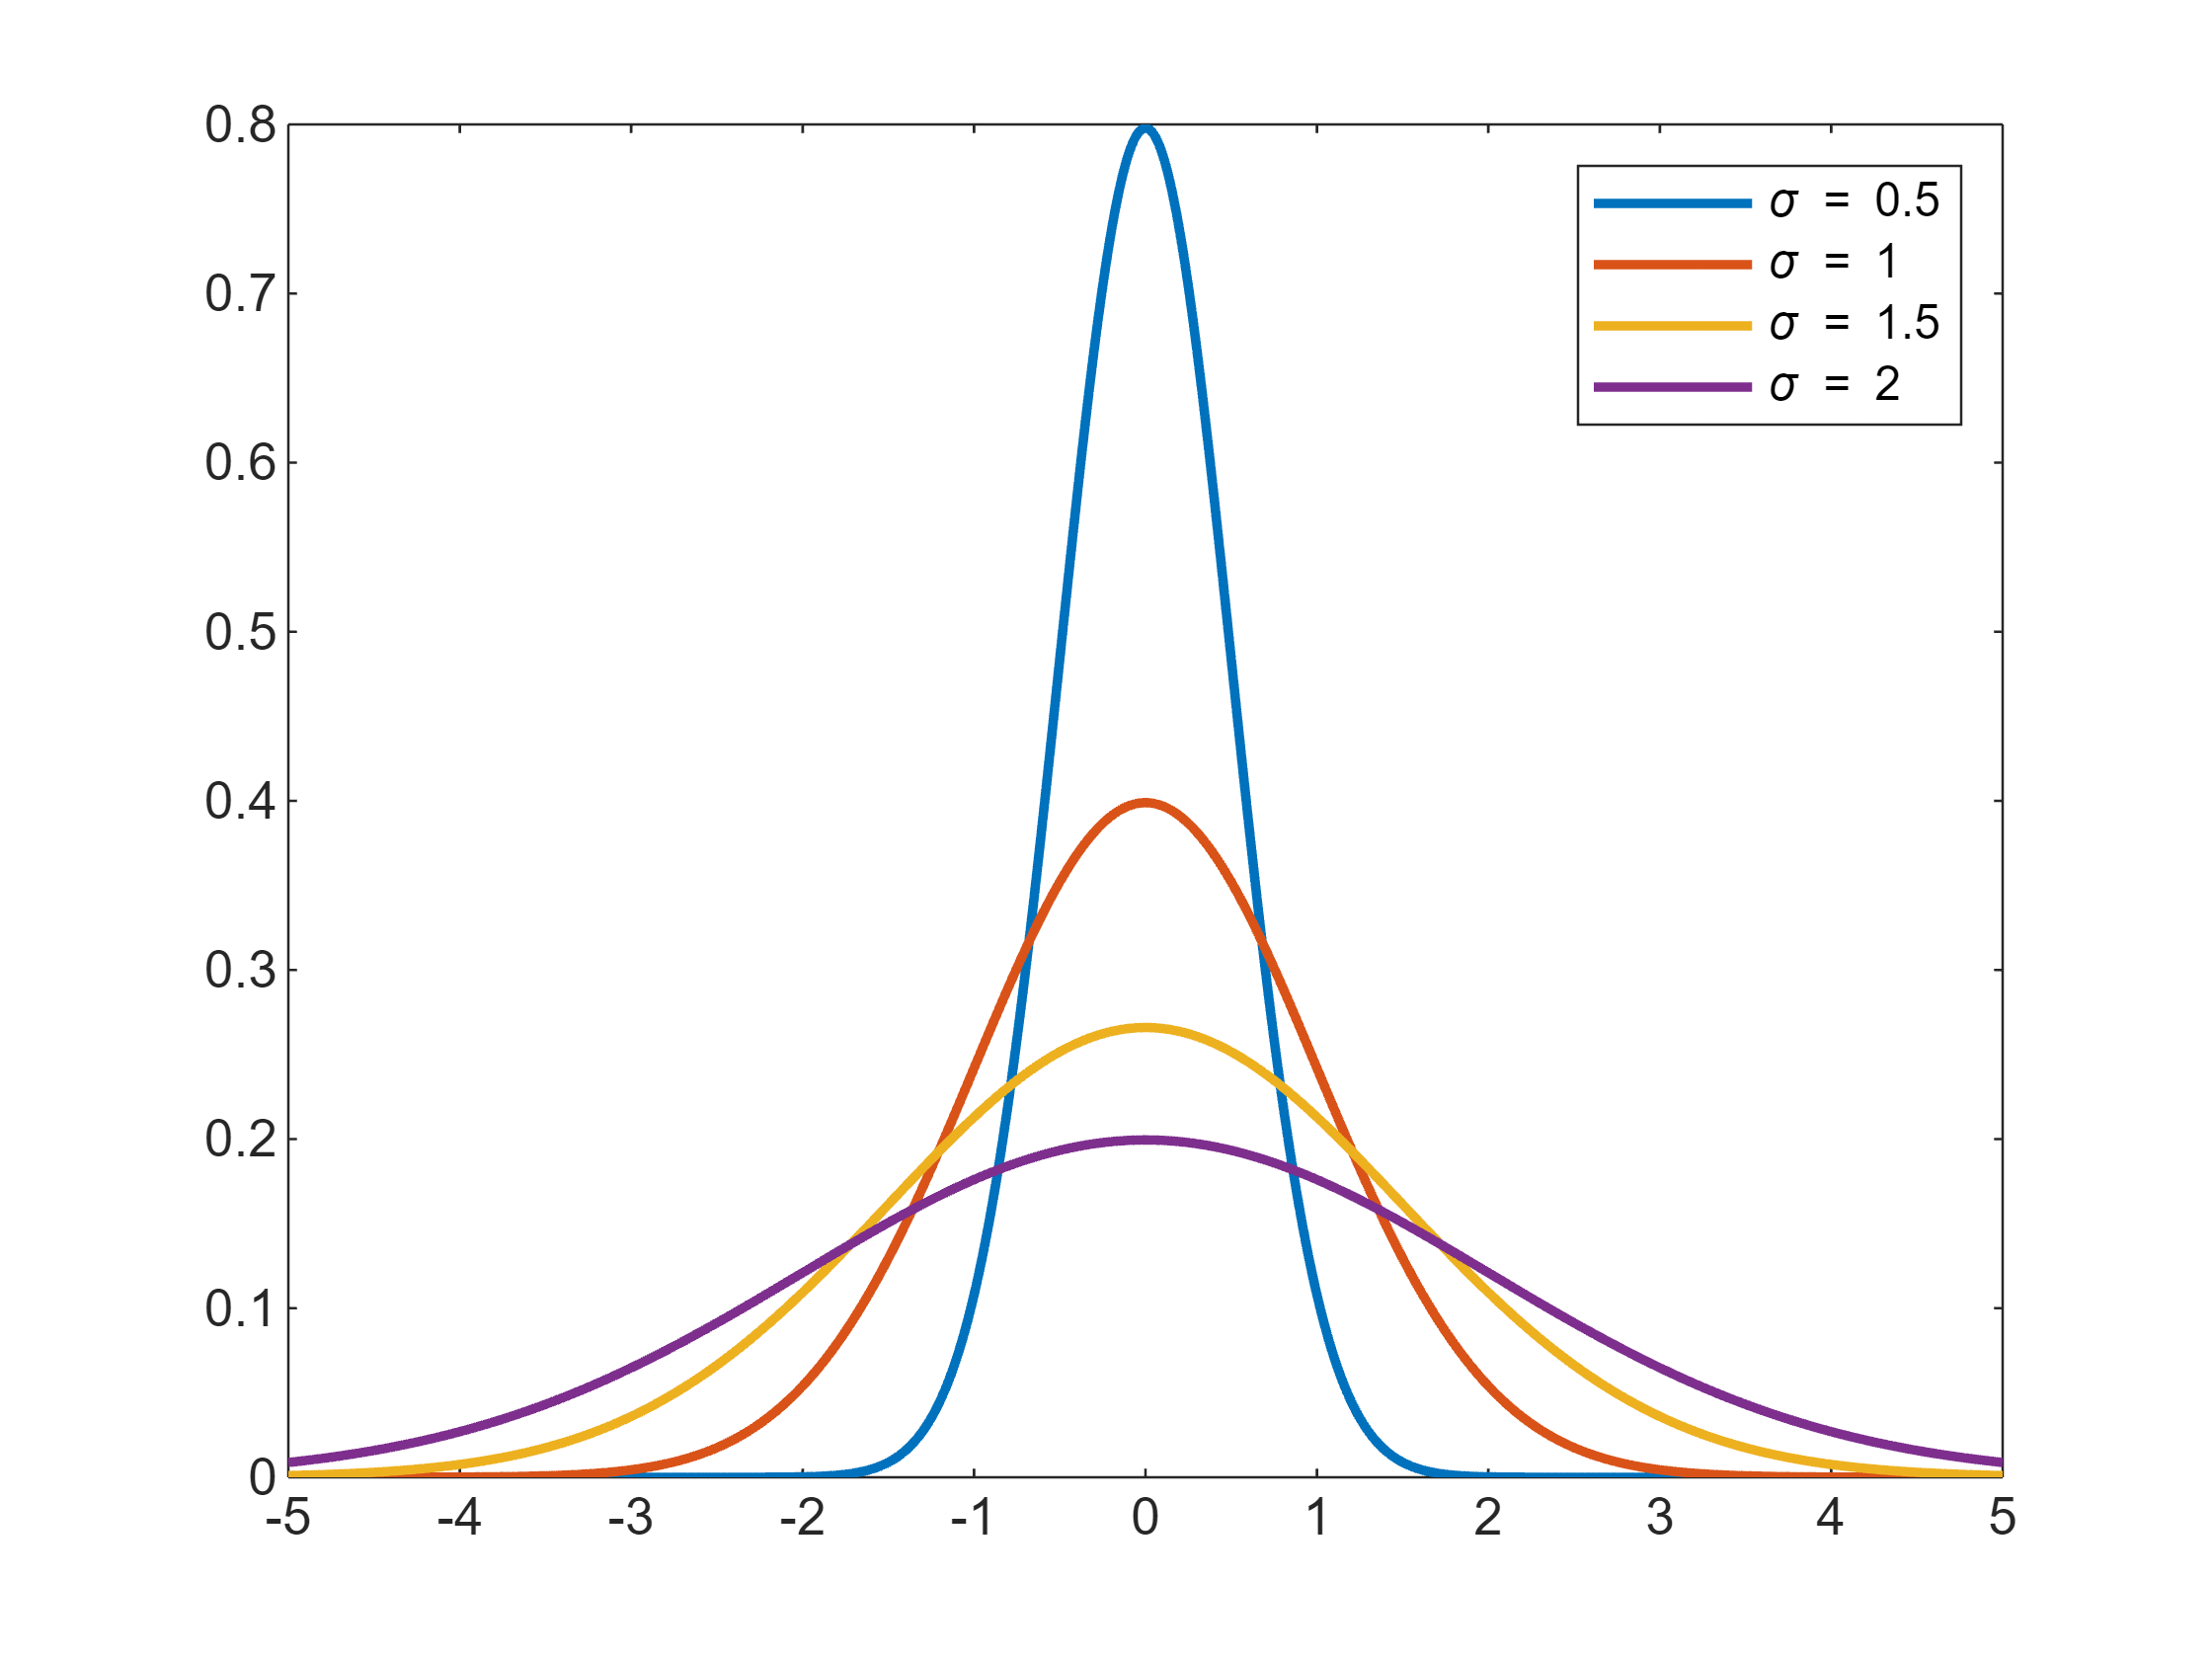

Sigma = 0.5:0.5:2;
mu = 0;
x = -5:0.01:5;
y = zeros(length(Sigma),length(x));
for ii = 1:length(Sigma)
    y(ii,:) = q1_4(x,mu,Sigma(ii));
end
close all
figure
plot(x,y,'LineWidth',1.8)
legend("\sigma = "+Sigma)
xticks(-5:1:5)
xticklabels(string(-5:1:5))

### **Q2** **分段函数的计算**

% q2_1(1)  
q2_1(4) 
q2_1(6) 
q2_1(8) 
q2_2([1 3 4 6 8 9 11]') 

x = 3:0.01:9;
y = q2_2(x);
close all
figure
plot(x,y,'-b','LineWidth',3)

### **Q3** **利用网格搜索法求函数的最大值**

[x_max1,y_max1] = q3(0,10,0.01)
[x_max2,y_max2] = q3(0,10,0.0001)
[x_max3,y_max3] = q3(-10,10,0.0001)
[x_max4,y_max4] = q3(-100,100,0.01)

x = 0:0.001:10;
y = 2*x.*sin(8*x)+x.*cos(3*x);
[y_max,ind] = max(y);
x_max = x(ind);
close all
figure
plot(x,y,'-b','LineWidth',1)
hold on
plot(x_max,y_max,'*r','MarkerSize',10)
text(x_max,y_max,'  最大值处', ...
    'HorizontalAlignment','left')
hold off

### **Q4** **利用经纬度计算两点之间的距离**

cs = {'沈阳';'长春';'哈尔滨';'北京';'天津';'呼和浩特';'银川';'太原';'石家庄';'济南';'郑州';'西安';'武汉';'南京';'合肥';'上海';
    '长沙';'南昌';'杭州';'福州';'广州';'台北';'海口';'南宁';'重庆';'昆明';'贵阳';'成都';'兰州';'西宁';'拉萨';'乌鲁木齐';'香港';'澳门'};
wd = [41.796768;43.886841;45.756966;39.904987;39.125595;40.84149;38.48644;37.857014;38.045475;36.675808;
  34.757977;34.263161;30.584354;32.041546;31.861191;31.231707;28.19409;28.676493;30.287458;26.075302;
  23.125177;25.030724;20.04422;22.82402;29.533155;25.040609;26.578342;30.659462;36.06138;36.61729;
  29.64415;43.82663;22.27534;22.19875];
jd = [123.429092;125.324501;126.642464;116.405289;117.190186;111.75199;106.23248;112.549248;114.502464;
  117.000923;113.665413;108.948021;114.298569;118.76741;117.283043;121.472641;112.982277;115.892151;
  120.15358;119.306236;113.28064;121.520076;110.19989;108.320007;106.504959;102.71225;106.713478;
  104.065735;103.83417;101.77782;91.1145;87.61688;114.16546;113.54913];

x = [123.429092 41.796768];
y = [125.324501 43.886841];
jwdist(x,y)

第1小问：计算各城市两两之间的距离，将结果保存到矩阵D中，其中D里面第i行第j列的元素表示第i个城市和第j个城市之间的距离。

n = length(jd);
D = zeros(n,n);
for ii = 1:n
    for jj = 1:ii  % 只需要到ii即可
        x = [jd(ii),wd(ii)];
        y = [jd(jj),wd(jj)];
        d = jwdist(x,y);
        D(ii,jj) = d;
        D(jj,ii) = d;  % D是对称矩阵
    end
end
D

D = 1.0e+03 *

         0    0.2791    0.5103    0.6269    0.6054    0.9802    1.5046    1.0262    0.8674    0.7937    1.1557    1.5168    1.4899    1.1607    1.2319    1.1876    1.7838    1.6099    1.3129    1.7884    2.2800    1.8726    2.7205    2.5343    2.0417    2.6636    2.2779    2.1249    1.8060    1.9463    3.1900    2.9071    2.3362    2.3660
    0.2791         0    0.2325    0.8601    0.8590    1.1638    1.7019    1.2641    1.1154    1.0673    1.4242    1.7675    1.7686    1.4359    1.5102    1.4471    2.0627    1.8878    1.5793    2.0536    2.5580    2.1249    2.9995    2.8123    2.3050    2.9286    2.5492    2.3756    2.0194    2.1462    3.4007    2.9967    2.6125    2.6432
    0.5103    0.2325         0    1.0570    1.0688    1.3205    1.8602    1.4580    1.3183    1.2903    1.6415    1.9680    1.9974    1.6684    1.7421    1.6757    2.2918    2.1199    1.8100    2.2836    2.7901    2.3497    3.2305    3.0392    2.5154    3.1397    2.7674    2.5740    2.1878    2.3026   

第2小问：哪两个城市距离最近、哪两个城市距离最远？

% 找到距离最近的两个城市
DD = D; % 将距离矩阵的对角线元素设置为无穷大（inf）来排除掉两个一样的城市
DD(logical(eye(size(D,1)))) = inf;
[minDist, minIndex] = min(DD(:));  
[row, col] = ind2sub(size(D), minIndex);   
% 显示结果  
fprintf('最近的城市对：%s 和 %s，距离为 %.2f km\n', ...
     cs{row}, cs{col}, minDist);  

最近的城市对：澳门 和 香港，距离为 64.00 km


% 找到距离最远的两个城市  
[maxDist, maxIndex] = max(D(:));  
[row, col] = ind2sub(size(D), maxIndex);  
fprintf('最远的城市对：%s 和 %s，距离为 %.2f km\n', ...
     cs{row}, cs{col}, maxDist);

最远的城市对：乌鲁木齐 和 台北，距离为 3705.96 km


第3小问：哪一个城市到其他所有的城市的距离之和最小？

% 计算每个城市到其他城市的距离之和  
distanceSums = sum(D, 1)  

distanceSums = 1.0e+04 *

    5.4498    6.1952    6.8548    4.1891    4.0948    4.3396    4.3009    3.7094    3.7448    3.7189    3.3746    3.5488    3.3676    3.6866    3.5074    4.1897    3.5746    3.6127    3.9887    4.4128    4.5120    5.0111    5.4552    4.8236    3.9088    5.1887    4.2408    4.2275    4.3464    4.7804    7.4720    8.8012    4.7558    4.7538


% 找到距离之和最小的城市  
[minSum, minCityIndex] = min(distanceSums) 

minSum = 3.3676e+04

minCityIndex = 13

closestCityToAll = cs{minCityIndex};  
% 显示结果  
fprintf('到其他所有城市距离之和最小的城市是：%s\n', closestCityToAll);

到其他所有城市距离之和最小的城市是：武汉


拓展：绘制武汉到其他城市的辐射图（下一章我们会介绍绘图的内容）

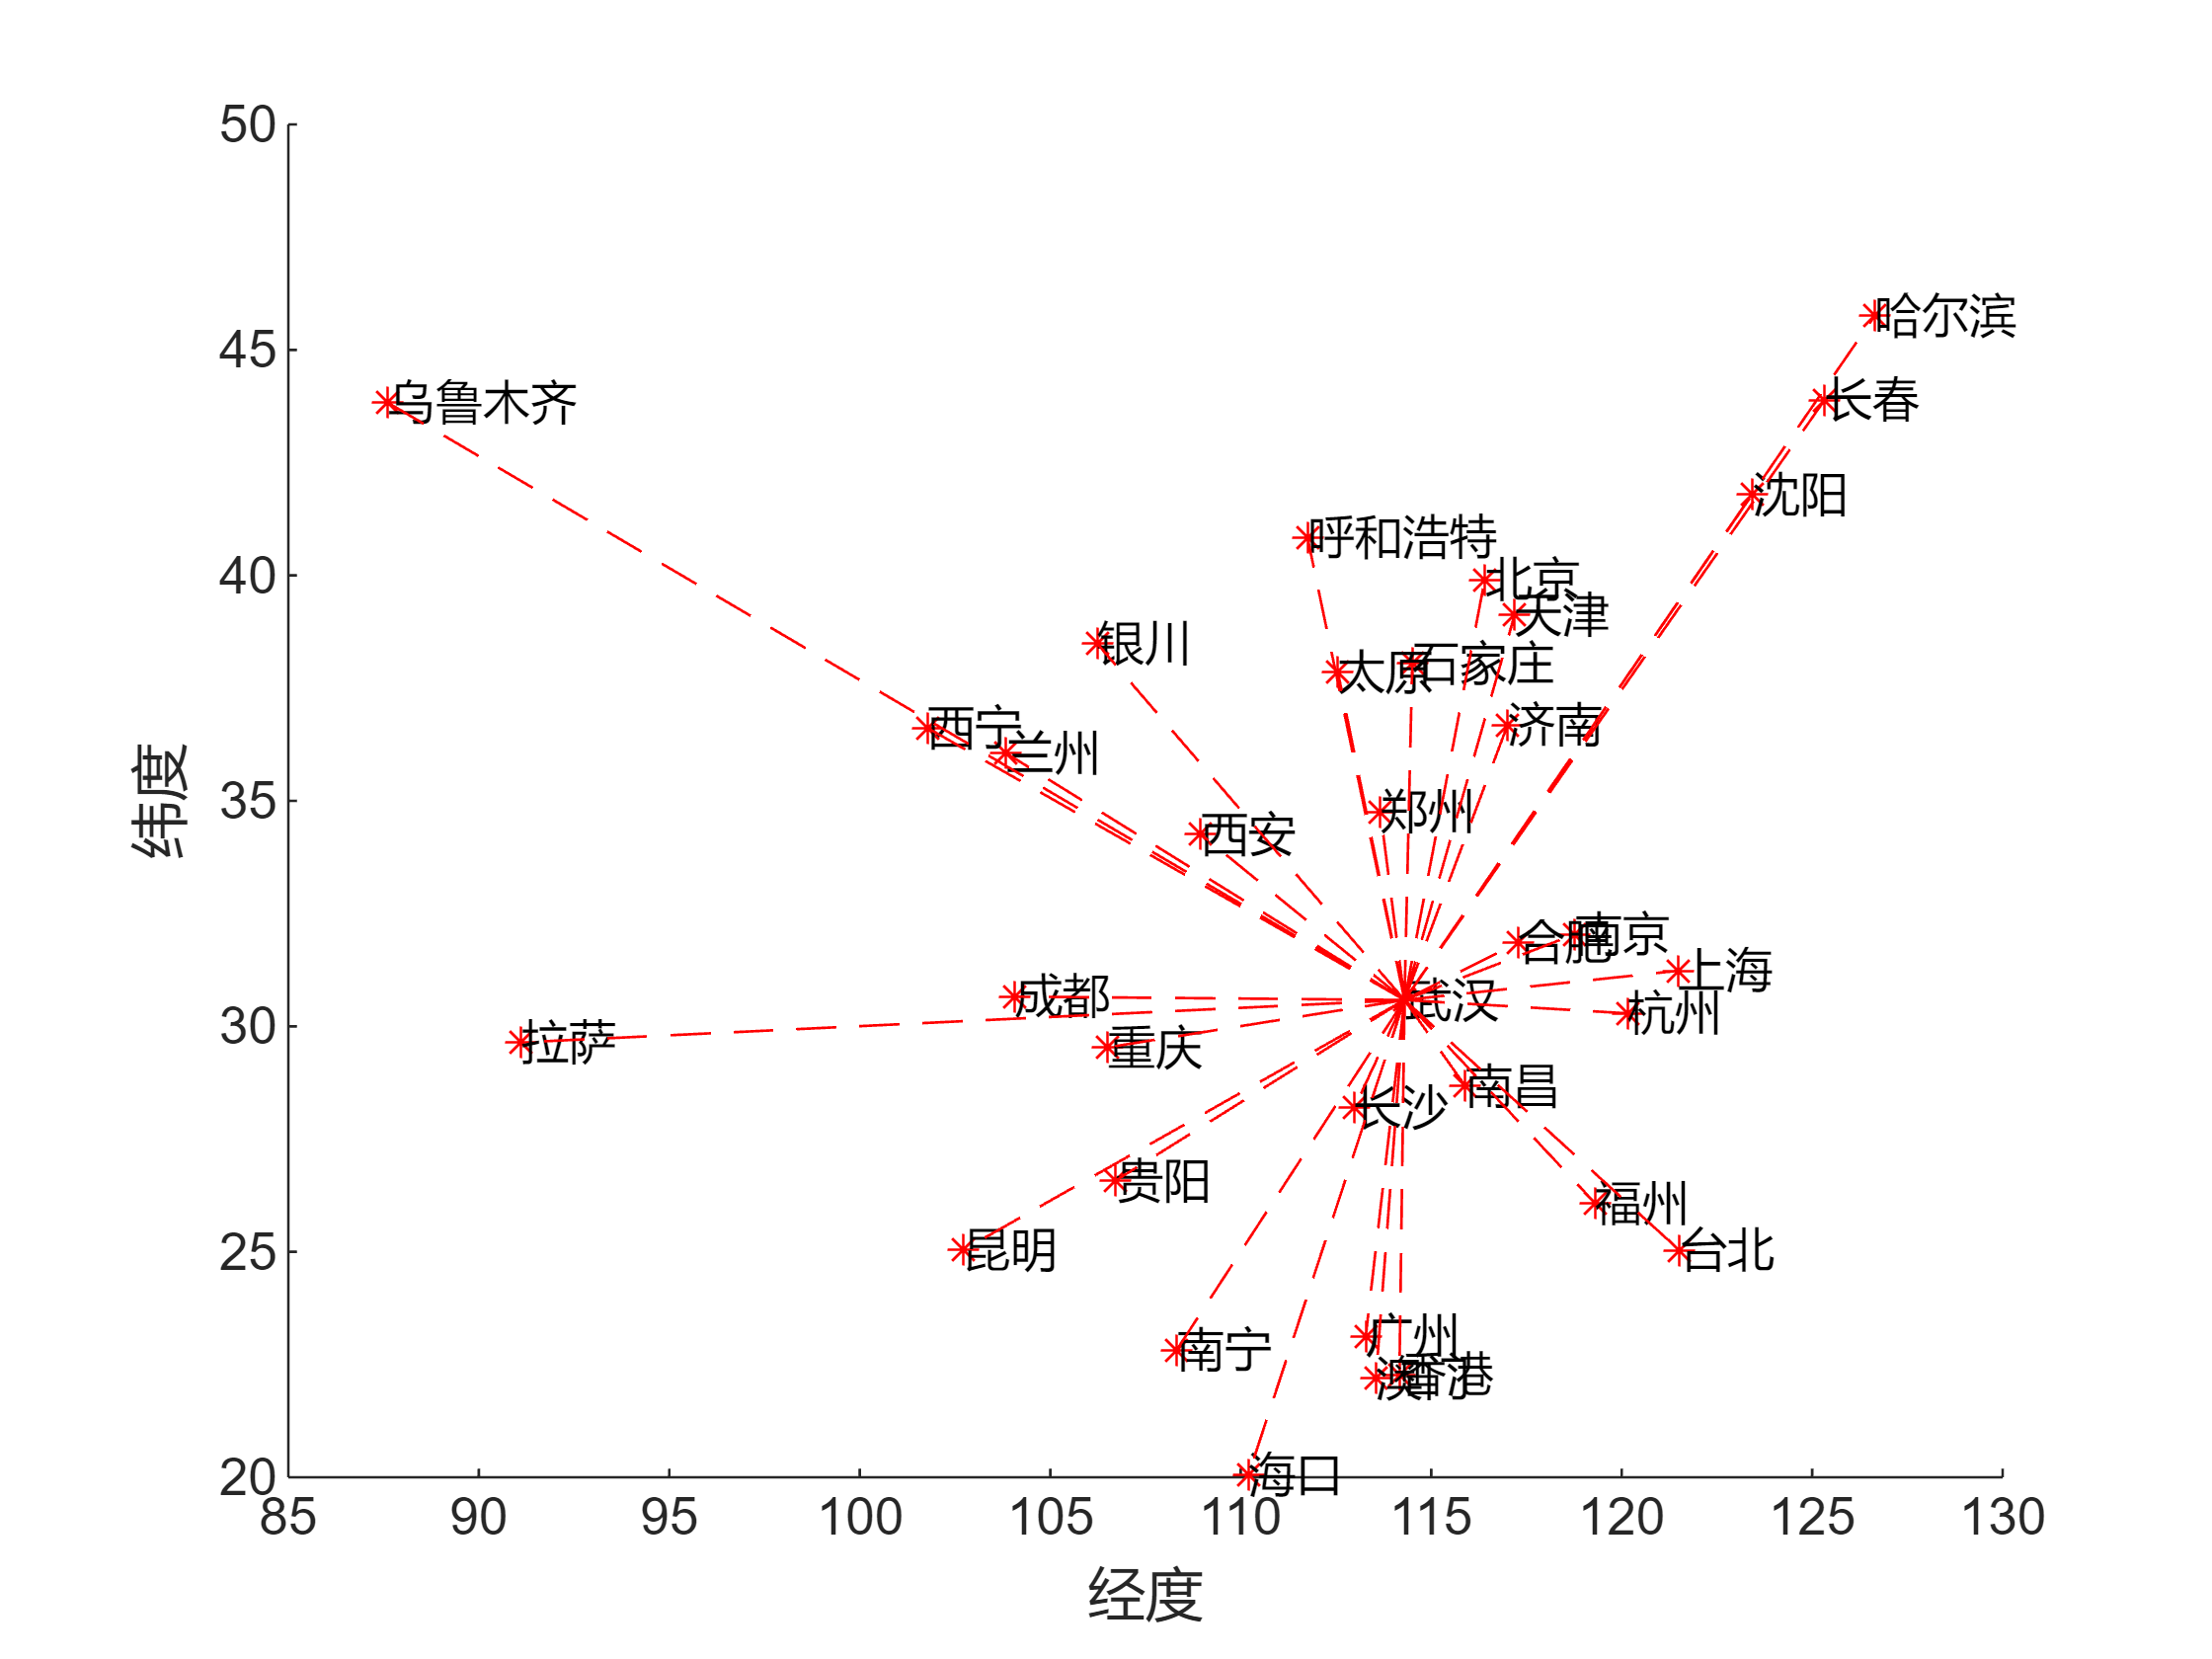

close all
figure
scatter(jd,wd,'*r')
for i = 1:length(jd)
  text(jd(i),wd(i),cs{i},'FontSize',9)
end
hold on
wh_wd = wd(minCityIndex); % 武汉的纬度
wh_jd = jd(minCityIndex); % 武汉的经度
for ii = 1:length(jd)
  if ii ~= minCityIndex % 除武汉之外
    geo_wd = [wh_wd,wd(ii)];
    geo_jd = [wh_jd,jd(ii)];
    plot(geo_jd,geo_wd,'--r','LineWidth',0.5)
  end
end
xlabel('经度');ylabel('纬度');
hold off

### **Q5** **填补缺失值**

A = [NaN 5  7 NaN 6 NaN NaN];
q5(A,'constant',10) 

ans =     10     5     7    10     6    10    10


v = mean(A,'omitnan');
q5(A,'constant',v) 
q5(A,'previous')
q5(A,'next')

### **Q6 ****使用递归计算****Hermite****多项式**

q6(1, 3) 
q6(2, 3) 
q6(4, 3)
q6(10, 3)

### **Q7** **计算连根式**

q7(3.5, 6)
q7(10, 30)

q7_recursion(3.5, 6)
q7_recursion(10, 30)

### **Q8**** Excel****列名称和序号的转换**

q8('Z')

ans = 26

q8(26)

ans = 'Z'

q8('CK')

ans = 89

q8(89) 

ans = 'CK'

q8(5176) 

ans = 'GQB'

q8('GQB') 

ans = 5176

### Q9 将分类数据转换为独热编码(One-Hot Encoding)

x1 = {'c' 'b' 'c' 'a' 'b' 'd' 'd' 'c'};
[D1,cats1] = one_hot(x1)
x2 = ["红色" "蓝色" "红色" "蓝色" "蓝色" "蓝色"];
[D2,cats2] = one_hot(x2)
x3 = categorical({'yes';'yes';'no';'no';'yes';'not sure'});
[D3,cats3] = one_hot(x3)
x4 = [1 0 0 1 1 0 0 0];
[D4,cats4] = one_hot(x4)

### **Q10**** RGB****颜色和十六进制颜色****(HEX color)****的转换**

rgb_hex([1 1 1])

rgb_hex([7 17 162])

rgb_hex('#F26BC1')

rgb_hex('#0711A2')

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1Xm41167aC/](https://www.bilibili.com/video/BV1Xm41167aC/)